## **Principles of Biosignals and Biomedical Imaging**

### **P3, 2nd Semester 2022/2023**

# **Vectors**

## **Lab Session 1**

### **Instituto Superior Técnico**

***100290, Armando Gonçalves***

***100357, Patrícia Marques***

# **1) Synthetic data**

**a),b),c) ***x = chirpTone(T, f1, f2, fs)*

fs = 4000

fs = 4000

s = chirpTone(10, 100, 2000, fs)

s =     0.9996    0.9916    0.9591    0.9030    0.8245    0.7256    0.6087    0.4766    0.3327    0.1805    0.0237   -0.1338   -0.2880   -0.4351   -0.5714   -0.6935   -0.7984   -0.8833   -0.9462   -0.9854   -0.9999   -0.9893   -0.9539   -0.8945   -0.8125   -0.7100   -0.5896   -0.4542   -0.3073   -0.1525    0.0062    0.1648    0.3193    0.4657    0.6004    0.7199    0.8211    0.9015    0.9589    0.9919    0.9995    0.9816    0.9385    0.8714    0.7819    0.6723    0.5453    0.4043    0.2528    0.0948


%soundsc(s)

audiowrite('uii.wav',s, fs);

**2) Real data**

% Read the audio data
[audioData, Fs] = audioread('Let It Be.mp3');


% Get the number of samples
numSamples = size(audioData, 1);

% Calculate the length of the audio file in seconds
audioLength = numSamples / Fs

audioLength = 243.1097



reverse = flipud(audioData);%to reverse the audioData
audiowrite("mundoaocontrario.wav", reverse, Fs);

%sound(reverse, Fs)


b) electrocardiogram

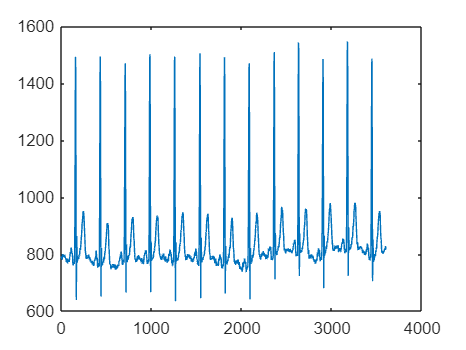

load("116m(2).mat");

plot(val) %the name of the var in the file is "val" by inspection


%comment?


Funções definidas:

function [x] = chirpTone(T, f1, f2, fs)
    step_t = 1/fs;
    t = 0:step_t:T;
    x = chirp(t,f1,T,f2,"linear",-pi/2);%the phase to transform chirp from cos to sin
end